# Problem Set III: Information Theory

clc; clear; close all;

## Problem 1

disp('Problem 1')

Problem 1



% Define symbols and respective probabilities
symbols =   {'a',  'b',  'c',  'd',  'e',  'f',  'g',  'h' };
p       =   [0.24, 0.21, 0.18, 0.15, 0.07, 0.06, 0.05, 0.04];

%%% Part (a)

### Part (a)

disp('Part (a)')

Part (a)


% Codeword lengths
l = ceil(-log2(p));

% Kraft sum
kraft_sum = sum(2.^(-l));

disp('Codeword lengths (l):');

Codeword lengths (l):


disp(l);

     3     3     3     3     4     5     5     5




% Show that Kraft inequality is satisfied
disp('Kraft Inequality:');

Kraft Inequality:


disp([num2str(kraft_sum) ' <= 1']);

0.65625 <= 1


if kraft_sum <= 1
    disp('The code lengths satisfy the Kraft inequality.');
else
    disp('The code lengths do not satisfy the Kraft inequality.');
end

The code lengths satisfy the Kraft inequality.


### Part (b)

disp('Part (b)')

Part (b)


% Entropy H(X)
H_X = sum(-p .* log2(p));

% Average code length L_bar
L_bar = sum(p .* l);

disp('Entropy H(X):');

Entropy H(X):


disp(H_X);

    2.7367



disp('Average code length L_bar:');

Average code length L_bar:


disp(L_bar);

    3.3700




% Verify the inequality H(X) <= L_bar < H(X) + 1
disp('H(X) <= L_bar < H(X) + 1')

H(X) <= L_bar < H(X) + 1


disp([num2str(H_X) ' <= ' num2str(L_bar) ' < ' num2str(H_X + 1)]);

2.7367 <= 3.37 < 3.7367


if H_X <= L_bar && L_bar < H_X + 1
    disp('The inequality H(X) <= L_bar < H(X) + 1 is satisfied.');
else
    disp('The inequality H(X) <= L_bar < H(X) + 1 is not satisfied.');
end

The inequality H(X) <= L_bar < H(X) + 1 is satisfied.


## Problem 2

disp('Problem 2')

Problem 2


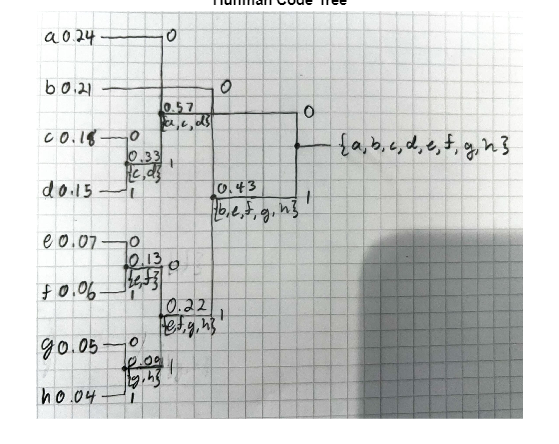


% Code Tree
img = imread('Code Tree.jpeg');
imshow(img);
title('Huffman Code Tree');


% Symbols         a     b     c      d      e       f       g        h
huffman_codes = {'00', '10', '010', '011', '1100', '1101', '1110', '1111'};

% Calculate Huffman code lengths
huffman_lengths = cellfun(@length, huffman_codes);

% Calculate -log2(p) for each probability
neg_log2_p = -log2(p);

% Code Table
code_table = table(symbols', p', huffman_codes', huffman_lengths', round(neg_log2_p, 2)', l', ...
                   'VariableNames', {'Symbol', 'Probability', 'Code', 'Length', '-log2(p)', 'ceil(-log2(p))'});
disp('Huffman Code Table:');

Huffman Code Table:


disp(code_table);

    Symbol    Probability      Code      Length    -log2(p)    ceil(-log2(p))
    ______    ___________    ________    ______    ________    ______________

    {'a'}        0.24        {'00'  }      2         2.06            3       
    {'b'}        0.21        {'10'  }      2         2.25            3       
    {'c'}        0.18        {'010' }      3         2.47            3       
    {'d'}        0.15        {'011' }      3         2.74            3       
    {'e'}        0.07        {'1100'}      4         3.84            4       
    {'f'}        0.06        {'1101'}      4         4.06            5       
    {'g'}        0.05        {'1110'}      4         4.32            5       
    {'h'}        0.04        {'1111'}      4         4.64            5       




% Kraft inequality for Huffman codes
kraft_sum_huffman = sum(2.^(-huffman_lengths));
disp('Kraft inequality (Huffman):');

Kraft inequality (Huffman):


disp([num2str(kraft_sum_huffman) ' <= 1']);

1 <= 1


if kraft_sum_huffman <= 1
    disp('The Huffman code lengths satisfy the Kraft inequality.');
else
    disp('The Huffman code lengths do not satisfy the Kraft inequality.');
end

The Huffman code lengths satisfy the Kraft inequality.



% Average code length L_bar for the Huffman code
L_bar_huffman = sum(p .* huffman_lengths);
disp('Average code length L_bar for Huffman code:');

Average code length L_bar for Huffman code:


disp(L_bar_huffman)

    2.7700




% Verify the inequality H(X) <= L_bar < H(X) + 1
disp('H(X) <= L_bar < H(X) + 1')

H(X) <= L_bar < H(X) + 1


disp([num2str(H_X) ' <= ' num2str(L_bar_huffman) ' < ' num2str(H_X + 1)]);

2.7367 <= 2.77 < 3.7367


if H_X <= L_bar_huffman && L_bar_huffman < H_X + 1
    disp('The inequality H(X) <= L_bar < H(X) + 1 is satisfied for the Huffman code.');
else
    disp('The inequality H(X) <= L_bar < H(X) + 1 is not satisfied for the Huffman code.');
end

The inequality H(X) <= L_bar < H(X) + 1 is satisfied for the Huffman code.


## Problem 3

disp('Problem 3')

Problem 3


### Part (a)

disp('Part (a)')

Part (a)



three_binit_sequences = {'000',     '001',     '010', '011', '100',     '101',     '110', '111'};
three_binit_probs     = [0.24*0.57, 0.24*0.43, 0.18,  0.15,  0.21*0.57, 0.21*0.43, 0.13,  0.09];
% sum_three_binit_probs = sum(three_binit_probs); % Check the sum of
% probabilities is 1

disp('3-Binit Sequence Probabilities:')

3-Binit Sequence Probabilities:


results_table = table(three_binit_sequences', round(three_binit_probs, 2)', ...
                      'VariableNames', {'3_Binit_Sequence', 'Probability'});
disp(results_table);

    3_Binit_Sequence    Probability
    ________________    ___________

        {'000'}            0.14    
        {'001'}             0.1    
        {'010'}            0.18    
        {'011'}            0.15    
        {'100'}            0.12    
        {'101'}            0.09    
        {'110'}            0.13    
        {'111'}            0.09    



### Part (b)

disp('Part (b)')

Part (b)



%% Entropy H(Y3)
% Marginal probabilities for Y3 (0 or 1)
p_Y3_0 = sum(three_binit_probs([1, 3, 5, 7])); % Sequences where Y3 = 0
p_Y3_1 = sum(three_binit_probs([2, 4, 6, 8])); % Sequences where Y3 = 1

H_Y3 = (-p_Y3_0 * log2(p_Y3_0) - p_Y3_1 * log2(p_Y3_1));
disp('Entropy H(Y3):')

Entropy H(Y3):


disp(H_Y3)

    0.9872




%% Entropy H(Y3 | Y2)
% Marginal probabilities for Y2 (0 or 1)
p_Y2_0 = sum(three_binit_probs([1, 2, 7, 8])); % Sequences where Y2 = 0
p_Y2_1 = sum(three_binit_probs([3, 4, 5, 6])); % Sequences where Y2 = 1

% Conditional probabilities for Y3 given Y2
p_Y3_0_given_Y2_0 = sum(three_binit_probs([1, 7])) / p_Y2_0;
p_Y3_1_given_Y2_0 = sum(three_binit_probs([2, 8])) / p_Y2_0;
p_Y3_0_given_Y2_1 = sum(three_binit_probs([3, 5])) / p_Y2_1;
p_Y3_1_given_Y2_1 = sum(three_binit_probs([4, 6])) / p_Y2_1;

H_Y3_given_Y2 = p_Y2_0 * (-p_Y3_0_given_Y2_0 * log2(p_Y3_0_given_Y2_0) - p_Y3_1_given_Y2_0 * log2(p_Y3_1_given_Y2_0)) ...
              + p_Y2_1 * (-p_Y3_0_given_Y2_1 * log2(p_Y3_0_given_Y2_1) - p_Y3_1_given_Y2_1 * log2(p_Y3_1_given_Y2_1));
disp('Conditional Entropy H(Y3 | Y2):')

Conditional Entropy H(Y3 | Y2):


disp(H_Y3_given_Y2)

    0.9867




%% Entropy H(Y3 | Y1, Y2)
% Joint probabilities of each (Y1, Y2) pair
p_Y1Y2_00 = sum(three_binit_probs([1, 2])); % (Y1, Y2) = (0, 0)
p_Y1Y2_01 = sum(three_binit_probs([3, 4])); % (Y1, Y2) = (0, 1)
p_Y1Y2_10 = sum(three_binit_probs([5, 6])); % (Y1, Y2) = (1, 0)
p_Y1Y2_11 = sum(three_binit_probs([7, 8])); % (Y1, Y2) = (1, 1)

% Conditional probabilities for Y3 given each (Y1, Y2) combination
% (Y1, Y2) = (0, 0)
p_Y3_0_given_Y1Y2_00 = three_binit_probs(1) / p_Y1Y2_00;
p_Y3_1_given_Y1Y2_00 = three_binit_probs(2) / p_Y1Y2_00;

% (Y1, Y2) = (0, 1)
p_Y3_0_given_Y1Y2_01 = three_binit_probs(3) / p_Y1Y2_01;
p_Y3_1_given_Y1Y2_01 = three_binit_probs(4) / p_Y1Y2_01;

% (Y1, Y2) = (1, 0)
p_Y3_0_given_Y1Y2_10 = three_binit_probs(5) / p_Y1Y2_10;
p_Y3_1_given_Y1Y2_10 = three_binit_probs(6) / p_Y1Y2_10;

% (Y1, Y2) = (1, 1)
p_Y3_0_given_Y1Y2_11 = three_binit_probs(7) / p_Y1Y2_11;
p_Y3_1_given_Y1Y2_11 = three_binit_probs(8) / p_Y1Y2_11;

% Combine the conditional entropies weighted by the probability of each (Y1, Y2) pair
H_Y3_given_Y1Y2 = p_Y1Y2_00 * (-p_Y3_0_given_Y1Y2_00 * log2(p_Y3_0_given_Y1Y2_00) - ...
                                p_Y3_1_given_Y1Y2_00 * log2(p_Y3_1_given_Y1Y2_00)) + ...
                  p_Y1Y2_01 * (-p_Y3_0_given_Y1Y2_01 * log2(p_Y3_0_given_Y1Y2_01) - ...
                                p_Y3_1_given_Y1Y2_01 * log2(p_Y3_1_given_Y1Y2_01)) + ...
                  p_Y1Y2_10 * (-p_Y3_0_given_Y1Y2_10 * log2(p_Y3_0_given_Y1Y2_10) - ...
                                p_Y3_1_given_Y1Y2_10 * log2(p_Y3_1_given_Y1Y2_10)) + ...
                  p_Y1Y2_11 * (-p_Y3_0_given_Y1Y2_11 * log2(p_Y3_0_given_Y1Y2_11) - ...
                                p_Y3_1_given_Y1Y2_11 * log2(p_Y3_1_given_Y1Y2_11));
disp('Conditional Entropy H(Y3 | Y1, Y2):')

Conditional Entropy H(Y3 | Y1, Y2):


disp(H_Y3_given_Y1Y2)

    0.9864



### Part (c)

disp('Part (c)')

Part (c)


disp('H(Y3) > H(Y3 | Y2) > H(Y3 | Y1, Y2)')

H(Y3) > H(Y3 | Y2) > H(Y3 | Y1, Y2)


disp(num2str(H_Y3) + " > " + num2str(H_Y3_given_Y2) + " > " + num2str(H_Y3_given_Y1Y2))

0.9872 > 0.98675 > 0.98637


if H_Y3 >= H_Y3_given_Y2 && H_Y3_given_Y2 >= H_Y3_given_Y1Y2
    disp('This is a decreasing sequence');
else
    disp('This is not a decreasing sequence');
end

This is a decreasing sequence


## Problem 4

disp('Problem 4')

Problem 4



pi0 = 0.5; % P(X = 0)
p = 0.1;   % error probability

% P(Y = 0)
py0 = pi0 * (1 - p) + (1 - pi0) * 2*p;

fprintf('P(Y = 0) = %.4f\n', py0);

P(Y = 0) = 0.5500
